root_folder = 'E:\Project_A\project_share\Project_A_image_full';
train_folder = 'train';
class_folder = 'class';
full_path_train = fullfile(root_folder, train_folder);
full_path_class = fullfile(root_folder, class_folder);

 %% Load pretrain network
    net=googlenet;
    analyzeNetwork(net);
    inputSize = net.Layers(1).InputSize;
    

    %% Load data
    imds = imageDatastore(full_path_train, ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames'); 
    %% split train & validation
    [imdsTrain,imdsValidation] = splitEachLabel(imds,0.875);

    imdsTest = imageDatastore(full_path_class, ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');
    augimdsTest = augmentedImageDatastore(inputSize,imdsTest,"ColorPreprocessing","gray2rgb");

    %% Replace final layer
    lgraph = layerGraph(net);
    [learnableLayer,classLayer] = findLayersToReplace(lgraph);
    [learnableLayer,classLayer] 

ans =   1×2 Layer array with layers:

     1   'loss3-classifier'   Fully Connected         1000 fully connected layer
     2   'output'             Classification Output   crossentropyex with 'tench' and 999 other classes

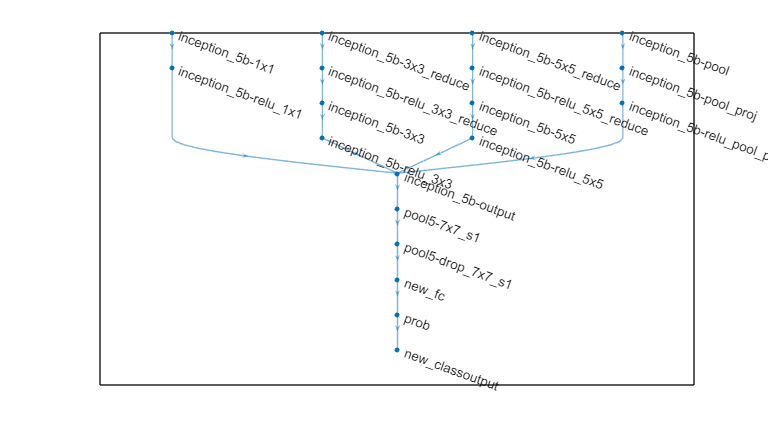

    numClasses = numel(categories(imdsTrain.Labels));
    if isa(learnableLayer,'nnet.cnn.layer.FullyConnectedLayer')
    newLearnableLayer = fullyConnectedLayer(numClasses, ...
        'Name','new_fc', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
    
    elseif isa(learnableLayer,'nnet.cnn.layer.Convolution2DLayer')
    newLearnableLayer = convolution2dLayer(1,numClasses, ...
        'Name','new_conv', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
    end

    lgraph = replaceLayer(lgraph,learnableLayer.Name,newLearnableLayer);

    newClassLayer = classificationLayer('Name','new_classoutput');
    lgraph = replaceLayer(lgraph,classLayer.Name,newClassLayer);

    figure('Units','normalized','Position',[0.3 0.3 0.4 0.4]);
    plot(lgraph)
    ylim([0,10])

    %% Freeze Intial layers
%     layers = lgraph.Layers;
%     connections = lgraph.Connections;
% 
%     layers(1:10) = freezeWeights(layers(1:10));
%     lgraph = createLgraphUsingConnections(layers,connections);
%     

    %% Train
    pixelRange = [-30 30];
    scaleRange = [0.9 1.1];
    imageAugmenter = imageDataAugmenter( ...
    'RandXReflection',true, ...
    'RandXTranslation',pixelRange, ...
    'RandYTranslation',pixelRange, ...
    'RandXScale',scaleRange, ...
    'RandYScale',scaleRange);
    augimdsTrain = augmentedImageDatastore(inputSize,imdsTrain, ...
    'DataAugmentation',imageAugmenter,'ColorPreprocessing','gray2rgb');
    augimdsValidation = augmentedImageDatastore(inputSize,imdsValidation,"ColorPreprocessing","gray2rgb");
    

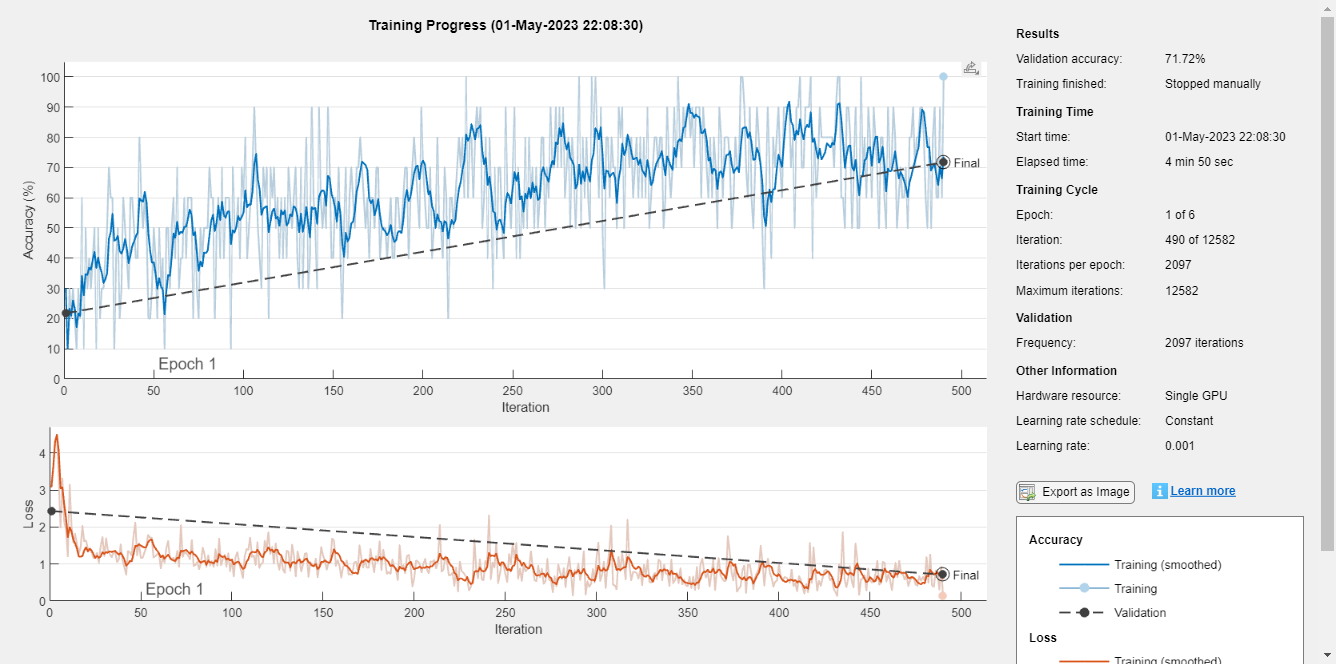

    miniBatchSize = 10;
    valFrequency = floor(numel(augimdsTrain.Files)/miniBatchSize);
    options = trainingOptions('sgdm', ...
    'MiniBatchSize',miniBatchSize, ...
    'MaxEpochs',6, ...
    'InitialLearnRate',1e-3, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augimdsValidation, ...
    'ValidationFrequency',valFrequency, ...
    'Verbose',false, ...
    'Plots','training-progress');
    options.ExecutionEnvironment = 'gpu';
    net = trainNetwork(augimdsTrain,lgraph,options);

    %% CLassify valid

    [YPred,probs] = classify(net,augimdsValidation);
    accuracy_train = mean(YPred == imdsValidation.Labels)

accuracy_train = 0.7172

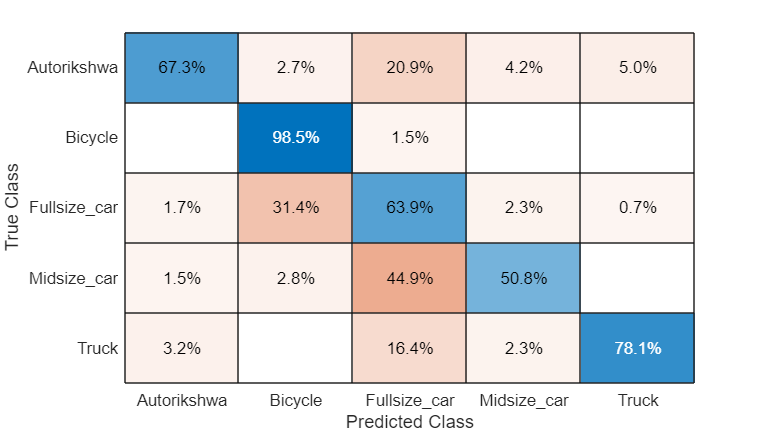

    confusionchart(imdsValidation.Labels,YPred,'Normalization','row-normalized')


    %% CLassify
    
    
    [YPred1,probs1] = classify(net,augimdsTest);

    accuracy_test = mean(YPred1 == imdsTest.Labels)

accuracy_test = 0.7819

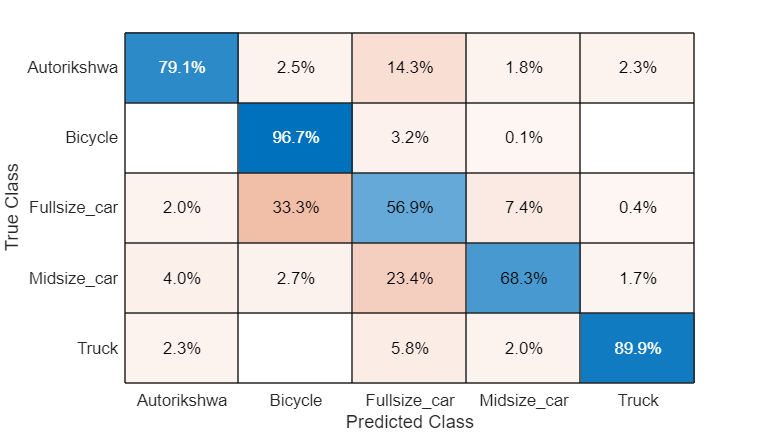

    confusionchart(imdsTest.Labels,YPred1,'Normalization','row-normalized')

    f1 = calculateF1score(imdsTest.Labels,YPred1)